addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
hamr6_F = false;
switch hamr6_F
    case true
        dataName = 'Data\HAMR6_SE2_kinematics.mat';
        dataMotPlanName = 'Data\HAMR6_SE2_kinematics_motionplan.mat';
    case false
        dataName = 'Data\case_1_kinematics.mat';
        dataMotPlanName = 'Data\case_1_kinematics_motionplan.mat';
end
load(dataName); load(dataMotPlanName);

sIdx = 5; % choose legs 1 and 3 for the first contact state 

any(kin.cs_IdxFor2bGaits == sIdx)

ans = 1×2 logical array
   1   0


find(any(kin.cs_IdxFor2bGaits == sIdx))

ans = 1

find([false, false])


ans =

  1×0 empty double row vector



kin.cs(5, :) % the current stance phase we are looking at

ans =      1     3


% this stance phase belongs to which two-beat gait?
% ... we know this is trot, but here's a programmatic way to obtain the
% ... same, helps automate most of the gait design process
sIdxLoc = find(any(kin.cs_IdxFor2bGaits == sIdx));
switch sIdxLoc
    case 1
    case 2
    otherwise
        error('ERROR! The indices should be between 1 and 4.');
end
cs_i = kin.cs(kin.cs_IdxFor2bGaits(:, 1), :) % the current stance phase

cs_i =      1     2
     2     3
     1     3


cs_j = kin.cs_IdxFor2bGaits(:, 2)

cs_j =      3
     4
     6


% get the integration limits
alpha_limits = [p_info{sIdx}.xlimits;
                p_info{sIdx}.ylimits]

alpha_limits =    -1.5708    1.5708
   -1.5708    1.5708


% plot the theta-panel
kin.dz_psi_theta{sIdx}

ans = function_handle with value:
    @(a,l,alpha_1,alpha_3)-(a.^2.*1.0./sqrt((sqrt(2.0).*cos(alpha_1+pi./4.0).*2.0-a.*sin(alpha_1-alpha_3)).^2+(sqrt(2.0).*cos(alpha_3+pi./4.0).*2.0+a.*sin(alpha_1-alpha_3)).^2).*(sin(alpha_1-alpha_3).*4.0-a.*cos(alpha_1.*2.0-alpha_3)+a.*sin(alpha_1.*2.0-alpha_3)+a.^2.*sin(alpha_1-alpha_3)+(a.^2.*sin(alpha_1.*2.0-alpha_3.*2.0))./2.0-a.*cos(alpha_1)+a.*cos(alpha_3)+a.*sin(alpha_1)-a.*sin(alpha_3)+a.*cos(alpha_1-alpha_3.*2.0)+a.*sin(alpha_1-alpha_3.*2.0)))./(abs(a).*(a.^2.*cos(alpha_1-alpha_3)+a.*cos(alpha_1).*2.0+a.*cos(alpha_3).*2.0+a.*sin(alpha_1).*2.0+a.*sin(alpha_3).*2.0+a.^2+4.0))


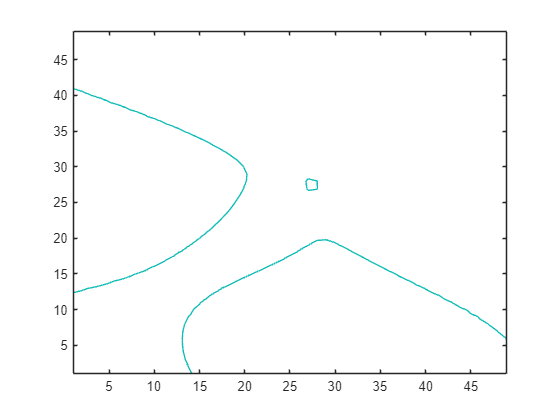

m =          0   14.1724   14.0000   13.7798   13.4335   13.2223   13.1111   13.0875   13.1570   13.3506   13.7557   14.0000   14.3067   15.0000   15.1255   16.0000   16.1594   17.0000   17.4525   18.0000   19.0000   19.0686   20.0000   20.7749   21.0000   22.0000   22.5146   23.0000   24.0000   24.1647   25.0000   25.6533   26.0000   26.9922   27.0000   28.0000   29.0000   30.0000   30.4966   31.0000   32.0000   32.0432   33.0000   33.5557   34.0000   35.0000   35.0668   36.0000   36.6827   37.0000
   70.0000    1.0000    1.4464    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000    9.2944   10.0000   10.7733   11.0000   11.7953   12.0000   12.5967   13.0000   13.3026   13.9458   14.0000   14.5257   15.0000   15.1130   15.6869   16.0000   16.2875   16.9013   17.0000   17.5861   18.0000   18.3078   19.0000   19.0094   19.6920   19.7855   19.3709   19.0000   18.7264   18.0306   18.0000   17.3585   17.0000   16.6820   16.0339   16.0000   15.3744   15.0000   14

m = contour(peaks, [0 0])